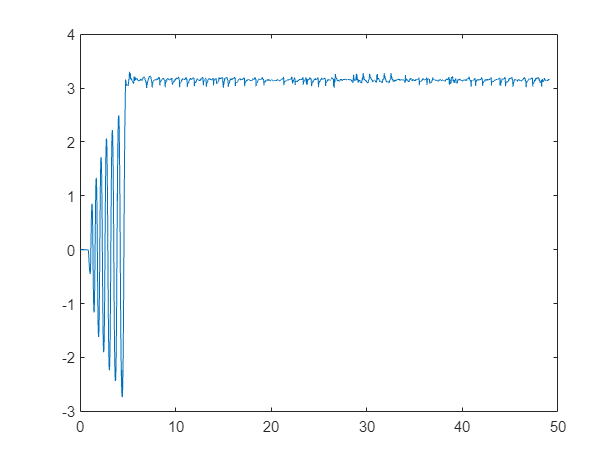

clc; clear; close all;
load("rmsTest.mat")
triggerTimeIndex = 942;

rmsTest.one.baseAngle(1:2100) =[];
rmsTest.one.time(1:2100) =[];
rmsTest.one.time = rmsTest.one.time - rmsTest.one.time(1);

rmsTest.one.pendAngleZeroDwn(1:2100) =[];
rmsTest.one.pendAngleZeroUp(1:2100) =[];
rmsTest.one.timeTrigger(1:2100) =[];
rmsTest.one.Current(1:2100) =[];rmsTest.one.Current = rmsTest.one.Current + 0.033;

plot(rmsTest.one.time, rmsTest.one.pendAngleZeroDwn)

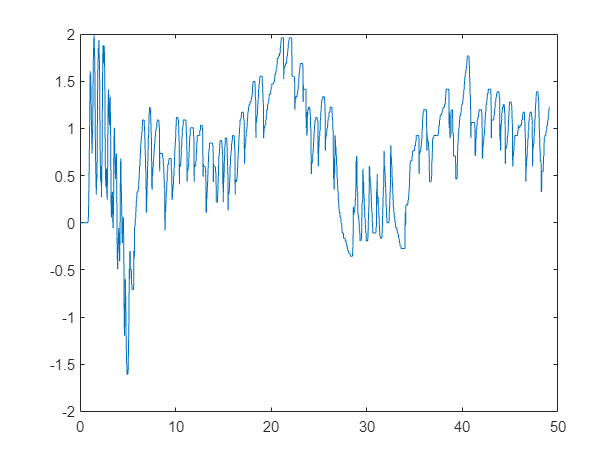

plot(rmsTest.one.time, rmsTest.one.baseAngle)

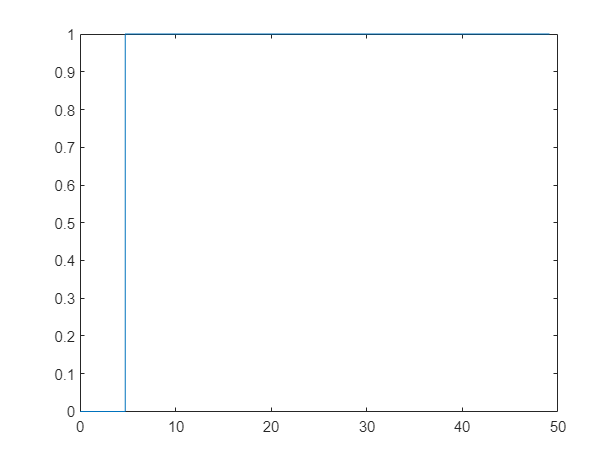

plot(rmsTest.one.time, rmsTest.one.timeTrigger)

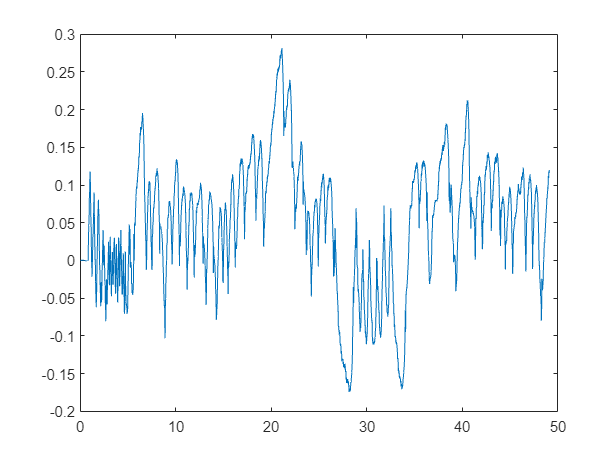

plot(rmsTest.one.time, rmsTest.one.Current)

Plotting paramters 

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

Plotting for the report pendulum swing-up

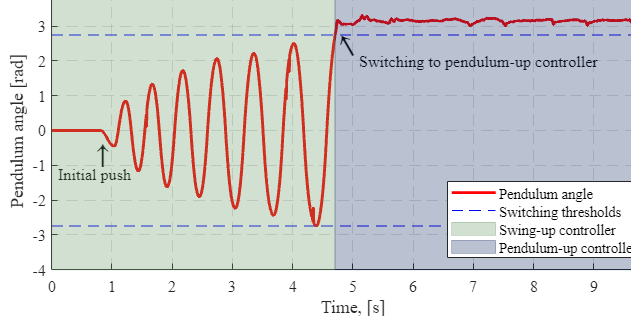

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.pendAngleZeroDwn(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

plt2 = plot([0, lengthOfPltTime], [pi-0.4, pi-0.4]);
plt2.Color = 'b';
plt2.LineStyle = '--';

plt3 = plot([0, lengthOfPltTime], [-pi+0.4, -pi+0.4]);
plt3.Color = 'b';
plt3.LineStyle = '--';

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-5:1:5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

% First arrow
arrow1 = text();
arrow1.String = '\rightarrow';
arrow1.Position = [0.8,-1.2];
arrow1.FontSize = 20;
arrow1.Rotation = 90;

text1 = text();
text1.String = 'Initial push';
text1.Position = [0.1,-1.25];
text1.FontName = 'Times New Roman';
text1.FontSize = AxisFontSize;

%Second arrow
arrow2 = text();
arrow2.String = '\rightarrow';
arrow2.Position = [5,2];
arrow2.FontSize = 20;
arrow2.Rotation = 120;

text2 = text();
text2.String = 'Switching to pendulum-up controller';
text2.Position = [5.1,2];
text2.FontName = 'Times New Roman';
text2.FontSize = AxisFontSize;

yl = [-4, 4];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)


yl = [-4, 4];
patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)


leg = legend('Pendulum angle', 'Switching thresholds','', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";

hold off
grid on
box on

Plotting fo the repport. Base under swing up

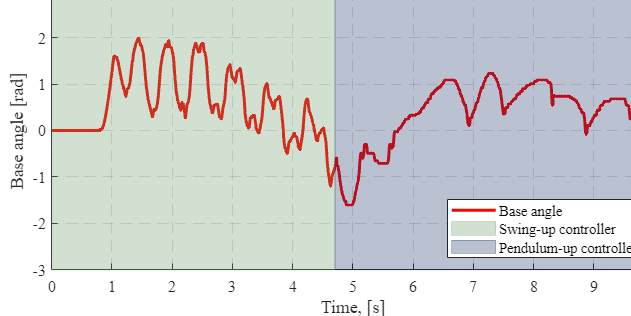

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.baseAngle(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-5:1:5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Base angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [-3, 3];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Base angle', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";

hold off
grid on
box on

Plotting fo the repport. Current under swing up

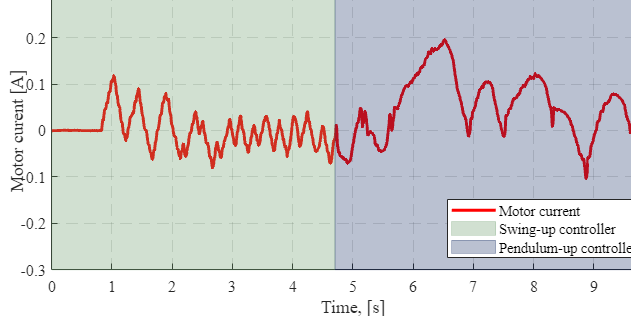

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.Current(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-0.5:0.1:0.5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Motor curent [A]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [-0.3, 0.3];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)


%yl = [-4, 4];
patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)



leg = legend('Motor current', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";

hold off
grid on
box on

Plotting for the report. Pendulum Up controller pendulum

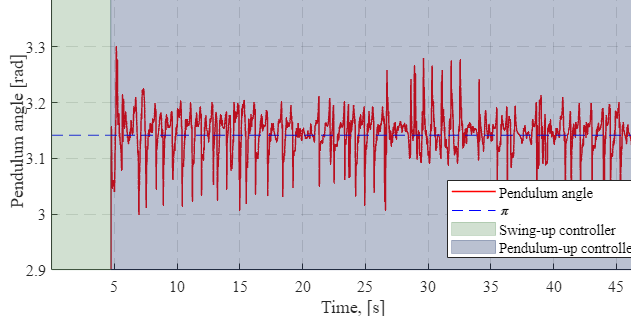

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 9825;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.pendAngleZeroDwn(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

plt2 = plot([0, lengthOfPltTime], [pi, pi]);
plt2.Color = 'b';
plt2.LineStyle = '--';

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-5:0.1:5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [2.9, 3.4];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Pendulum angle','\pi' , 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Plotting for the report. Pendulum Up controller base

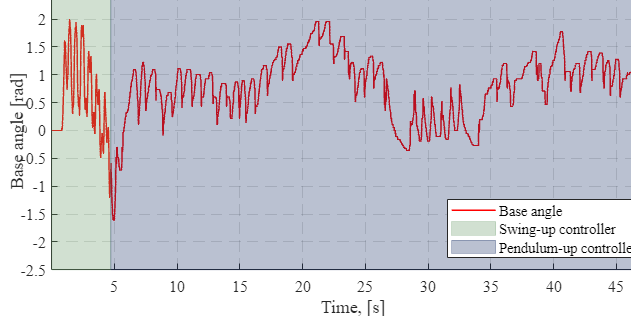

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 9825;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.baseAngle(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-5:0.5:5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Base angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [-2.5 2.5];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Base angle', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Plotting for the report. Pendulum Up controller base

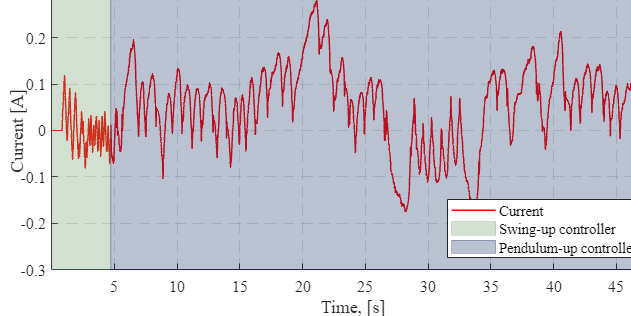

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 9825;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.Current(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-5:0.1:5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Current [A]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [-0.3 0.3];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Current', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Plotting for the report RMS implimentation

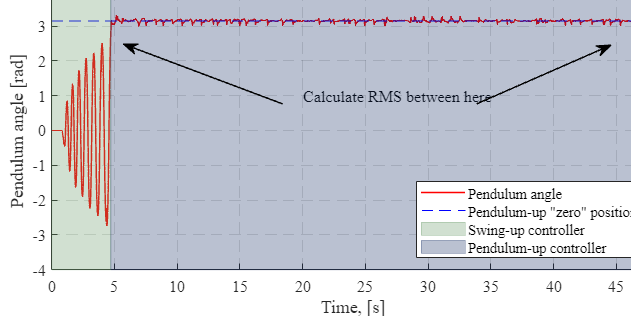

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 9700;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.pendAngleZeroDwn(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;


plt2 = plot([0, lengthOfPltTime], [pi, pi]);
plt2.Color = 'b';
plt2.LineStyle = '--';

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:5:60];                    % Divisions on axes
ax.YTick = [-5:1:5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

text1 = text();
text1.String = 'Calculate RMS between here';
text1.Position = [20,1];
text1.FontName = 'Times New Roman';
text1.FontSize = AxisFontSize;



% Create arrow
annotation(fig,'arrow',[0.755371900826446 0.968595041322314],...
    [0.671185430463576 0.857615894039735], 'LineWidth',1);


% Create arrow
annotation(fig,'arrow',[0.447933884297521 0.19504132231405],...
    [0.671185430463576 0.860927152317881], 'LineWidth',1);


yl = [-4, 4];
patch([0 0 4.705 4.705],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

yl = [-4, 4];
patch([4.705 4.705 lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Pendulum angle', 'Pendulum-up "zero" position','Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])

hold off
grid on
box on

Calculate RMS

tStartIndex = 942; % when t=4.705
tStopIndex = 8942; % When t=44.705


pendRMS = rms(rmsTest.one.pendAngleZeroDwn(tStartIndex:tStopIndex)-pi)

pendRMS = 0.0349

baseRMS = rms(rmsTest.one.baseAngle(tStartIndex:tStopIndex))

baseRMS = 0.9874

currentRMS = rms(rmsTest.one.Current(tStartIndex:tStopIndex))

currentRMS = 0.1043